# MA 590 : Computational Inverse Problems

# Homework 5

## Problem 1

Consider the Landweber iteration, where


$$x^{(k+1)} = x^{(k)} + \omega G^T (y - Gx^{(k)}) \quad \quad (1)$$


for $k = 0,1,...$ 

Define filter factors as


$$f_{i}^{(k)} = 1 - (1- \omega \sigma_i^2)^k \quad \quad (2)$$


## (a)

Claim: Equation (1) is satisfied when $x^{(k)} = \sum_{i=1}^{\text{min}(m,n)} f_i^{(k)} \frac{u_i^T y }{\sigma_i} v_i$ and $f_i^{(k)}$ defined as in equation (2). 

Proof: We define the notations,


$$f_{ik} := f_i^{(k)}$$



$$ x_k := x^{(k)} $$



$$\sum_i := \sum_{i}^{\text{min}(m,n)},$$


where $m,n$ reflect the dimension $m\times n$ of the matrix $G$. Also define $e_i$ to be the $i^{th}$ natural basis vector for $n$ dimensional Euclidean space. 

Every matrix admits a singular value decomposition. Assuming that $G$ is real valued, we write $G = U\Sigma V^T$ (we will assume this is the full SVD of $G$). Although the matrices $\Sigma$ and $\Sigma^T$ may not be square if $m \neq n$, the matrix $\Sigma^T \Sigma$ is a square diagonal matrix of dimension $n \times n$. We will define $\Sigma^2 = \Sigma^T \Sigma$. The elements on the diagonal of $\Sigma^2$ are the squares of the singular values $\sigma_i^2$ of $G$.

We begin with the right hand side of equation (1):


$$x_k + \omega G^T (y - Gx_k) = x_k + \omega V\Sigma^T U^T y - \omega V\Sigma^T U^T U \Sigma V^T x_k$$



$$= x_k + \omega V\Sigma^T U^T y - \omega V\Sigma^2 V^T x_k $$



$$= \sum_i f_{ik} \frac{u_i^T y }{\sigma_i} v_i + \omega V\Sigma^T U^T y - \omega V\Sigma^2 V^T \sum_i f_{ik} \frac{u_i^T y }{\sigma_i} v_i$$
 


$$= \sum_i f_{ik} \frac{u_i^T y }{\sigma_i} v_i + \omega V\Sigma^T U^T y - \omega  \sum_i f_{ik} \frac{u_i^T y }{\sigma_i} V\Sigma^2 V^T v_i$$
 


$$=\sum_i f_{ik} \frac{u_i^T y }{\sigma_i} v_i + \omega V\Sigma^T U^T y - \omega  \sum_i f_{ik} \frac{u_i^T y }{\sigma_i} V\Sigma^2 e_i$$



$$=\sum_i f_{ik} \frac{u_i^T y }{\sigma_i} v_i + \omega V\Sigma^T U^T y - \omega  \sum_i f_{ik} \frac{u_i^T y }{\sigma_i} V\sigma_i^2 e_i$$
 


$$=\sum_i f_{ik} \frac{u_i^T y }{\sigma_i} v_i + \omega V\Sigma^T U^T y - \omega  \sum_i f_{ik} \frac{u_i^T y }{\sigma_i} \sigma_i^2 V e_i$$


 
$$=\sum_i f_{ik} \frac{u_i^T y }{\sigma_i} v_i + \omega V\Sigma^T U^T y - \omega  \sum_i f_{ik} \frac{u_i^T y }{\sigma_i} \sigma_i^2 v_i$$



$$=\sum_i f_{ik} \frac{u_i^T y }{\sigma_i} v_i + \omega V\Sigma^T U^T y - \omega  \sum_i f_{ik} \sigma_i u_i^T y v_i$$



$$=\sum_i f_{ik} \frac{u_i^T y }{\sigma_i} v_i + \omega V \Sigma^T \sum_iu_i^T y- \omega  \sum_i f_{ik} \sigma_i u_i^T y v_i$$



$$=\sum_i f_{ik} \frac{u_i^T y }{\sigma_i} v_i + \omega V  \sum_i \sigma_i u_i^T y- \omega  \sum_i f_{ik} \sigma_i u_i^T y v_i$$



$$=\sum_i f_{ik} \frac{u_i^T y }{\sigma_i} v_i + \omega  \sum_i v_i (\sigma_i u_i^T y)- \omega  \sum_i f_{ik} \sigma_i u_i^T y v_i$$



$$=\sum_i f_{ik} \frac{u_i^T y }{\sigma_i} v_i + \omega \sum_i \sigma_i u_i^T y v_i- \omega  \sum_i f_{ik} \sigma_i u_i^T y v_i$$



$$=\sum_i \left[ f_{ik} \frac{u_i^T y }{\sigma_i} v_i + \omega \sigma_i u_i^T y v_i- \omega  f_{ik} \sigma_i u_i^T y v_i \right]$$



$$=\sum_i \left[ f_{ik} \frac{u_i^T y }{\sigma_i} v_i + \omega \sigma_i^2 \frac{u_i^T y }{\sigma_i} v_i - \omega  f_{ik} \sigma_i^2 \frac{u_i^T y }{\sigma_i} v_i  \right]$$



$$=\sum_i \frac{u_i^T y }{\sigma_i} v_i \left[ f_{ik} + \omega \sigma_i^2 - \omega \sigma_i^2  f_{ik}  \right]$$



$$=\sum_i \frac{u_i^T y }{\sigma_i} v_i \left[ 1 - (1- \omega \sigma_i^2)^k + \omega \sigma_i^2 - \omega \sigma_i^2 \left(1 - (1- \omega \sigma_i^2)^k\right)  \right]$$



$$=\sum_i \frac{u_i^T y }{\sigma_i} v_i \left[ 1 - (1- \omega \sigma_i^2)^k + \omega \sigma_i^2 - \omega \sigma_i^2 + \omega \sigma_i^2(1- \omega \sigma_i^2)^k  \right]$$



$$=\sum_i \frac{u_i^T y }{\sigma_i} v_i \left[ 1 - (1- \omega \sigma_i^2)^k + \omega \sigma_i^2(1- \omega \sigma_i^2)^k  \right]$$



$$=\sum_i \frac{u_i^T y }{\sigma_i} v_i \left[ 1 +(1- \omega \sigma_i^2)^k (\omega \sigma_i^2 - 1)\right]$$



$$=\sum_i \frac{u_i^T y }{\sigma_i} v_i \left[ 1 +(-1)(1- \omega \sigma_i^2)^k (1-\omega \sigma_i^2)\right]$$



$$=\sum_i \frac{u_i^T y }{\sigma_i} v_i \left[ 1-(1- \omega \sigma_i^2)^{k+1} \right]$$



$$=\sum_i \frac{u_i^T y }{\sigma_i} v_i \;f_{i,k+1}$$



$$=\sum_{i}^{\text{min}(m,n)} f_i^{(k+1)}\frac{u_i^T y }{\sigma_i} v_i$$



$$=x^{(k+1)} \;.$$


## (b)

We next implement the Landweber iteration for the Phillips’ test problem with n = 64 and noiseless data.

We will check whether the result for $x^{(10)}$ using the Landweber iteration matches the result for $x^{(10)}$ found as the (filter factor) SVD solution using various choices for $\omega$.

Warning: For some reason my live script has suddenly started plotting figure 8 before figures 1-7 below just before submitting the assignment. I don't why this would but want to mention this in case it causes confustion.

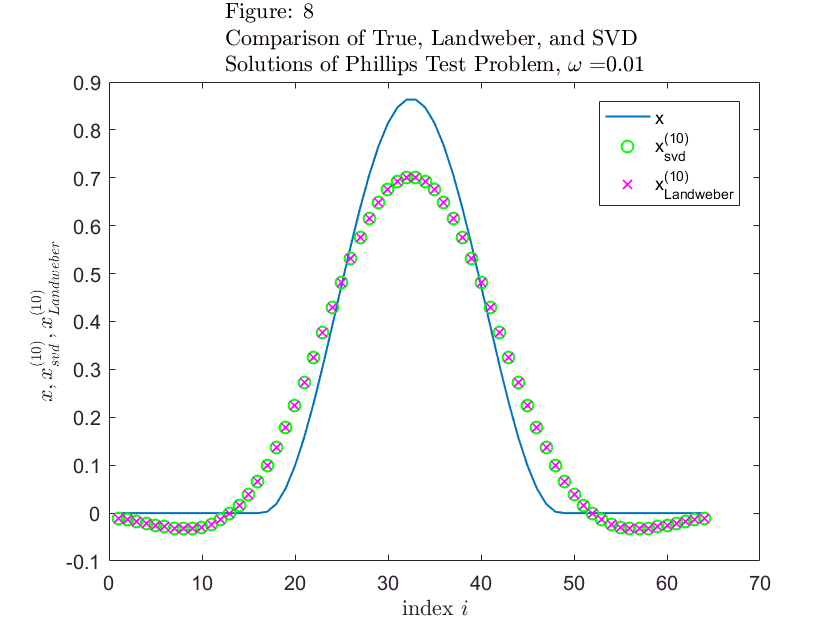

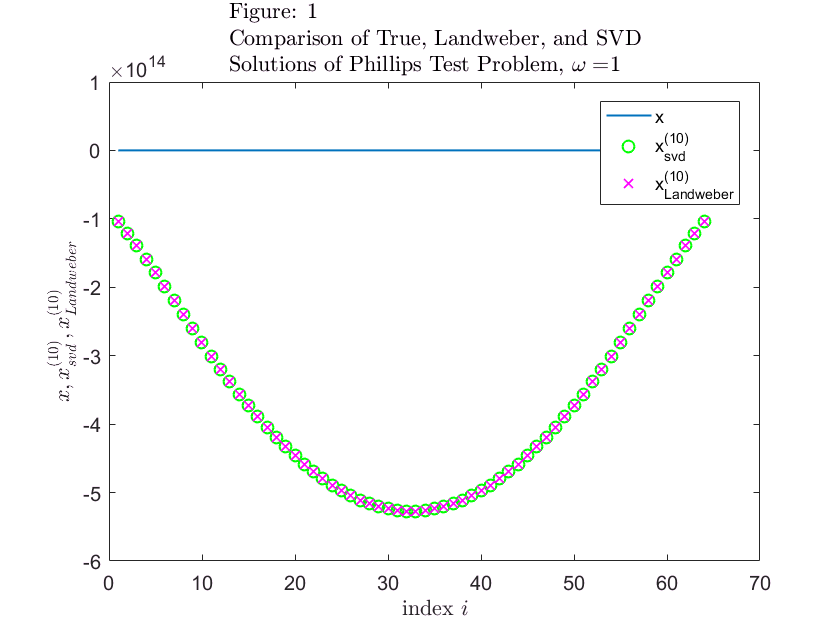

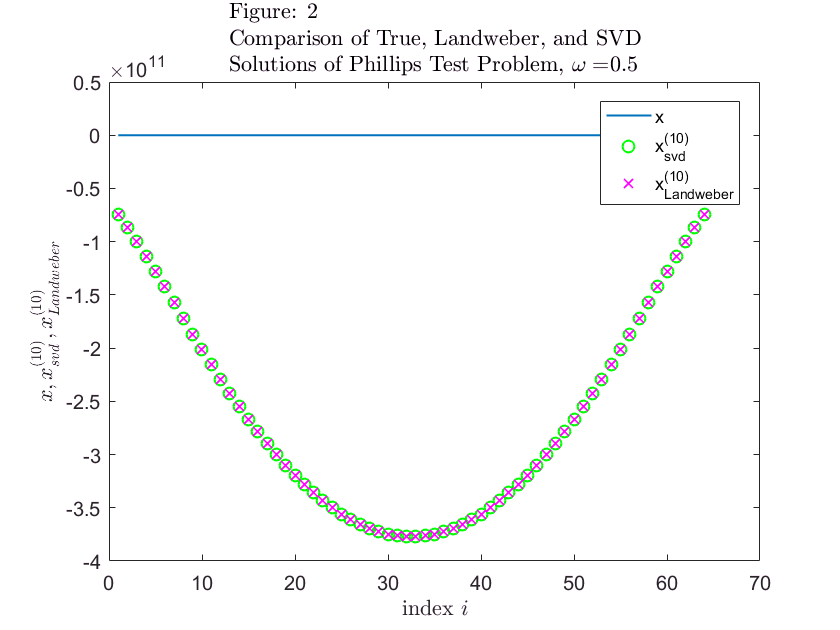

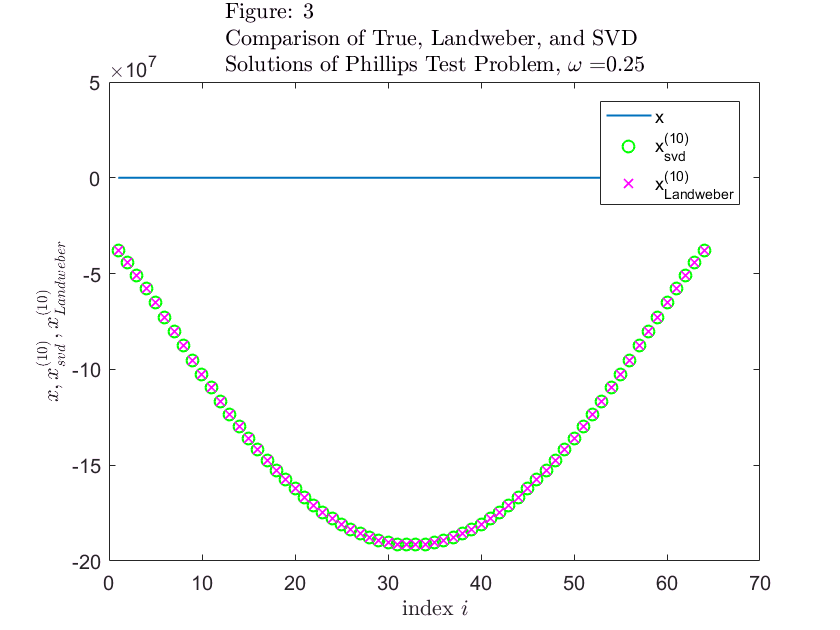

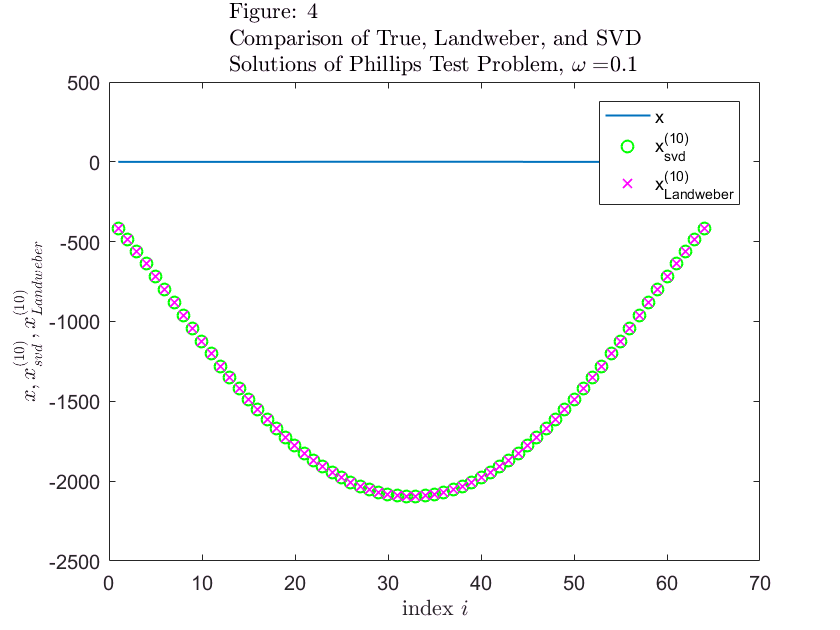

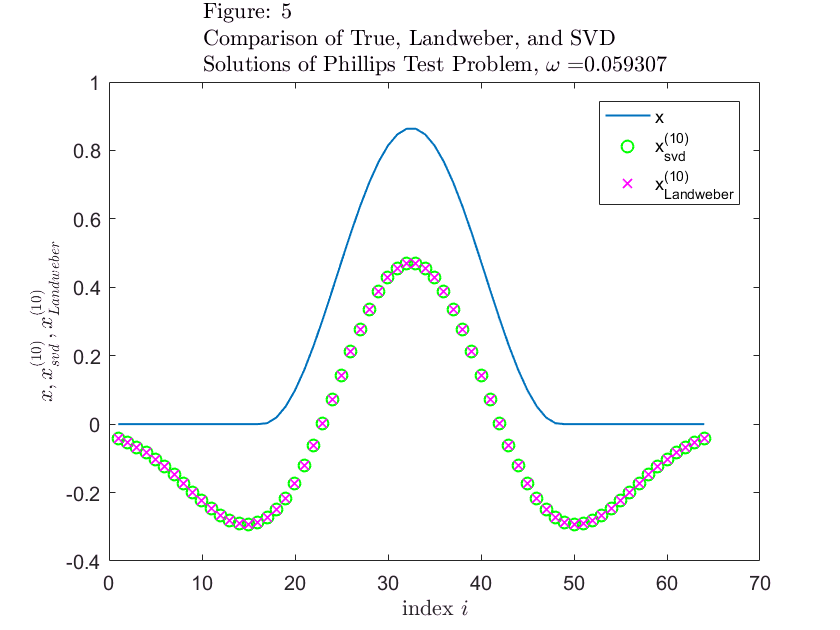

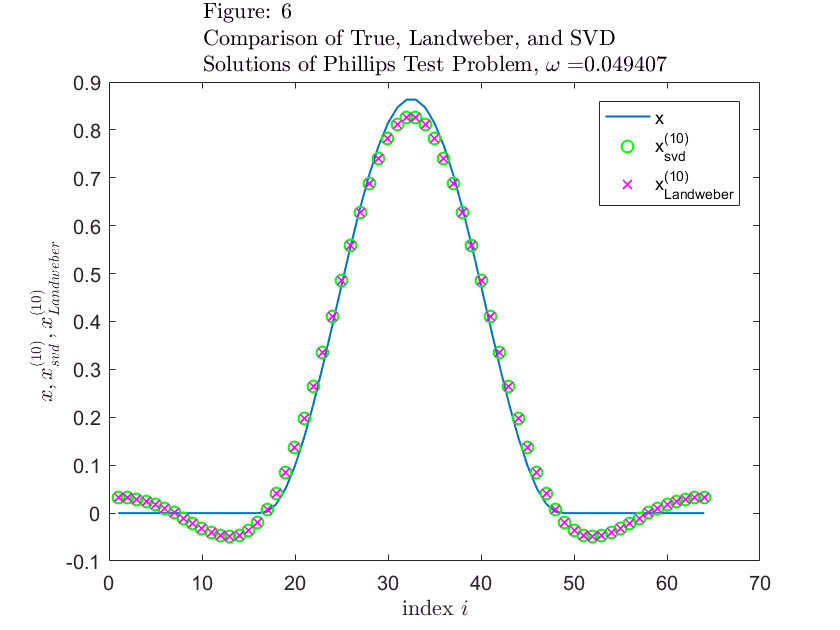

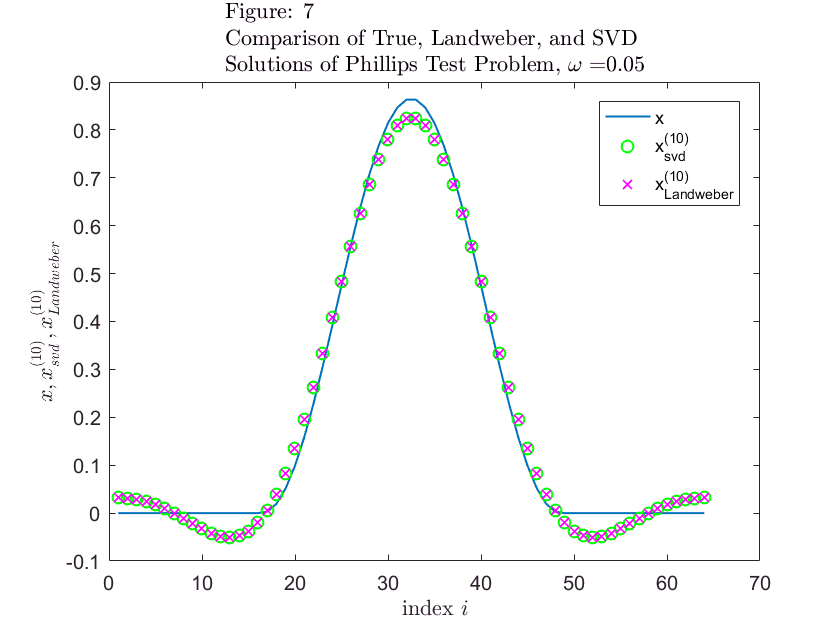

clear all
close all
clc

n = 64;
% Initializing Phillips Test Problem
[G, y, x] = phillips(n);
[U,S,V] = svd(G);
singular_values = diag(S);
omega_sup = 2 / S(1,1)^2;


%Test the claim from Problem 1a using various omega choices.
test_omegas = [1, 0.5, 0.25, 10^-1, omega_sup - 10^-4,...
    omega_sup-10^-2, 0.05, 10^-2]; 
%One way of comparing landweber vs svd results stored in error_norms.
relative_error_norms = zeros(1,length(test_omegas));

for test = 1:length(test_omegas)

% Matrix to store Landweber iterations. First column corresponds to x_0
% (here we use zero vector) and the i_th column corresponds to x_{i-1}.
X = zeros(64,1);
omega = test_omegas(test);
iterations = 10;

for k = 1:iterations
    
    % Landweber iteration given by equation (1).
    X(:,k+1) = X(:,k) + omega*G'*(y - G*X(:,k));
    
end

figure(test)
plot(1:n, x, 1:n, X(:,end))

%filter factors as defined by equation (2)
filters_10 = 1 - (1- omega*diag(S).^2).^10;



x_svd = 0;
for i = 1:n
    
    x_svd = x_svd + filters_10(i) * ...
        (U(:,i))' * y / singular_values(i) * V(:,i);
    
end

figure(test)
plot1 = plot(1:n, x, '-', 1:n, X(:,end), 'go',...
    1:n, x_svd, 'mx', 'linewidth',1);
title({['Figure: ' num2str(test)] ['Comparison of True, Landweber, and SVD']...
    ['Solutions of Phillips Test Problem, $$\omega = $$'...
    num2str(omega)]}, 'interpreter', 'latex');
xlabel('index $$i$$', 'interpreter', 'latex')
ylabel('$$x, x_{svd}^{(10)}, x_{Landweber}^{(10)}$$',...
    'interpreter', 'latex')
names = {'x', 'x_{svd}^{(10)}', 'x_{Landweber}^{(10)}'};
legend(plot1,names, 'location', 'northeast')

% Note that the 11th column of X is the iteration x_10.
relative_error_norms(test) = norm(x_svd - X(:,end))/norm(x_svd);

end

The plots suggest that the Landweber iteration results align well with the SVD (with filter factors) results. This holds even when (as in the case where $\omega = 1$) neither method is very successful in approximating the true solution. We can also see numerically that the two methods match using:

relative_error_norms % ||x^(10) - x_svd||_2 / ||x_svd||_2

relative_error_norms =    1.0e-13 *

    0.0768    0.0822    0.0834    0.1078    0.1801    0.0152    0.0167    0.0105


We found that $2/\sigma_1^2 \approx 0.0594$. From figures 5, 6, 7, and 8 we claim that the Landweber and (filter factor) SVD also approximate the true solution reasonably well (we know that these choices of $\omega$ will guarantee convergence but with $k=10$ the results may or may not be satisfactory depending on our error constraints). Choices of $\omega$ closer to $2/\sigma_1^2$ were better by the 10th iteration, but we can see from figures 5,6,7, and 8 that choosing $\omega$ increasingly close to $2/\sigma_1^2$ does not necessarily provide a better approximation for $k = 10$ (for example we have some improvement between figures 5 and 6 by putting extra distance between $\omega$ and $2/\sigma_1^2$. 

## Problem 2

## (a)

Let $A = G^TG$ for some $m\times n$ real valued matrix $G$. Since $A^T = G^T(G^T)^T = G^TG = A$, $A$ is symmetric and so by the spectral theorem $A$ is diagonalizable. That is, there exists an invertible matrix $P$ and a diagonal matrix $\Lambda$ (where the elements on the diagonal the eigenvalues of $A$) such that $A = P\Lambda P^{-1}$. We may assume that the eigenvalues along the diagonal of $\Lambda$ are sorted such that $\lambda_1 \geq ... \geq \lambda_n$ since otherwise we could just permute the rows of $\Lambda$ such that this holds using a permutation matrix (which would be invertible and so could be absorbed into the matrix $P$). Then,


$$A^k = (P\Lambda P^{-1})(P\Lambda P^{-1})....(P\Lambda P^{-1}) \quad \text{(multiplication of } P\Lambda P^{-1} \; k \text{ times)}$$



$$= P\Lambda (P^{-1} P) \Lambda (P^{-1} P) ... (P^{-1}P)\Lambda P^{-1} \quad \text{(by associativity)}$$
 


$$=P\Lambda^k P^{-1} \;.$$


Or this can be seen by induction on $k$. We already have the base case established and if we assume $A^k = P\Lambda P^{-1}$ then $A^{k+1} = AA^k = P\Lambda P^{-1}P\Lambda^k P^{-1} = P\Lambda^{k+1} P^{-1}$. 

## (b)

Let $x \in R^n$ be arbitrary. The columns of the matrix $P$ are eigenvectors corresponding to the eigenvalues on the diagonal of $\Lambda$ (sourced informally here: [https://www2.math.uconn.edu/~khlee/Teaching/LAlg/MAT223-8.pdf](https://www2.math.uconn.edu/~khlee/Teaching/LAlg/MAT223-8.pdf)). Call these $v_1,....,v_n$. The fact that $P$ is invertible implies that $\{v_1,...,v_n\}$ are a basis for $R^n$. This means there exist $\alpha_1,...,\alpha_n$ such that $x = \alpha_1 v_1 + ... + \alpha_n v_n$ so that  $Ax = \alpha_1 A v_1 + ... + \alpha_n A v_n = \alpha_1 \lambda_1 v_1 + ... + \alpha_n \lambda_n v_n$. Assume for $k\geq 1$ that  $A^k x= \alpha_1 \lambda_1^k v_1 + ... + \alpha_n \lambda_n^k v_n$. Consider $A^{k+1}x = AA^kx$. We have


$$A^{k+1}x = A( \alpha_1 \lambda_1^k v_1 + ... + \alpha_n \lambda_n^k v_n) =  \alpha_1 \lambda_1^k A v_1 + ... + \alpha_n \lambda_n^k A v_n =  \alpha_1 \lambda_1^{k+1} v_1 + ... + \alpha_n \lambda_n^{k+1} v_n \; ,$$
 

which establishes that $A^k x= \alpha_1 \lambda_1^k v_1 + ... + \alpha_n \lambda_n^k v_n$ for any choice of $k\geq 1$.

## (c)

Start with the random vector $x^{(0)} = \alpha_1 v_1 + ... +  \alpha_n v_n$ (where we have written $x^{(0)}$ as a linear combination of the eigenvectors of $A$ using part (b) with coeffieients $ \alpha_1, .. ,  \alpha_n$). Assume that $\alpha_1 \neq 0$.  We know that $\lambda_1 \geq ... \geq \lambda_n \geq 0$ but not necessarily whether any of these inequalities could be strict. Suppose first that $\lambda_1 = \lambda_2 = ... = \lambda_p \neq 0$ (we will try to handle the case that $\lambda_1 = 0$ later) for some $p \leq n$. Assume all norms are the 2 norm and that $x = x^{(0)}$ in what follows. Then,


$$\frac{||A^kx||}{||A^{k-1} x||} = \frac{||\alpha_1 \lambda_1^k v_1 +...+\alpha_p \lambda_p^kv_p+ ... + \alpha_n \lambda_n^k v_n||}{||\alpha_1 \lambda_1^{k-1} v_1 + ...+\alpha_p \lambda_p^{k-1}v_p+... + \alpha_n \lambda_n^{k-1} v_n||}$$
 


$$= \frac{||\alpha_1 \lambda_1^k v_1 +...+\alpha_p \lambda_1^kv_p+ ... + \alpha_n \lambda_n^k v_n||}{||\alpha_1 \lambda_1^{k-1} v_1 + ...+\alpha_p \lambda_1^{k-1}v_p+... + \alpha_n \lambda_n^{k-1} v_n||}$$
 


$$ = \frac{||\alpha_1\lambda_1 v_1 +...+\alpha_p\lambda_1v_p+ ... + \alpha_n \lambda_n\left(\frac{\lambda_n}{\lambda_1}\right)^{k-1} v_n||}{|| \alpha_1v_1 + ...+\alpha_p v_p+... + \alpha_n \left(\frac{\lambda_n}{\lambda_1}\right)^{k-1} v_n||}$$
 


$$= \frac{||\lambda_1(\alpha_1 v_1 +...+\alpha_pv_p)+ ... + \alpha_n \lambda_n\left(\frac{\lambda_n}{\lambda_1}\right)^{k-1} v_n||}{|| \alpha_1v_1 + ...+\alpha_p v_p+... + \alpha_n \left(\frac{\lambda_n}{\lambda_1}\right)^{k-1} v_n||} \; .$$


For $i>p$, since $\lambda_i < \lambda_1$, $lim_{k \rightarrow \infty} \left(\frac{\lambda_i}{\lambda_1}\right)^{k-1} = 0$. Note that if $p =n$ the last line of the computations would have come to  $$\frac{||\lambda_1(\alpha_1 v_1 +...+\alpha_pv_p)||}{|| \alpha_1v_1 + ...+\alpha_p v_p||} $$ and so this next claim still holds. It follows that


$$lim_{k \rightarrow \infty} \frac{||A^kx||}{||A^{k-1} x||} = lim_{k \rightarrow \infty} \frac{||\lambda_1(\alpha_1 v_1 +...+\alpha_pv_p)+ ... + \alpha_n \lambda_n\left(\frac{\lambda_n}{\lambda_1}\right)^{k-1} v_n||}{|| \alpha_1v_1 + ...+\alpha_p v_p+... + \alpha_n \left(\frac{\lambda_n}{\lambda_1}\right)^{k-1} v_n||}$$
 


$$=  \frac{||\lambda_1(\alpha_1 v_1 +...+\alpha_pv_p)||}{|| \alpha_1v_1 + ...+\alpha_p v_p||}$$
 


$$= |\lambda_1 | \frac{||\alpha_1 v_1 +...+\alpha_pv_p||}{|| \alpha_1v_1 + ...+\alpha_p v_p||}$$
 


$$= \lambda_1 \frac{||\alpha_1 v_1 +...+\alpha_pv_p||}{|| \alpha_1v_1 + ...+\alpha_p v_p||}$$
 


$$\lambda_1 \;.$$


Since the steps we took so far would still be valid if $p = 1$, which is the case that $\lambda_1 > \lambda_i$ for $i = 2,...,n$, this shows that $lim_{k \rightarrow \infty} \frac{||A^kx||}{||A^{k-1} x||} = \lambda_1$ for any $\lambda_1 \neq 0$. If $\lambda_1 = 0$, then $\lambda_i = 0$ for all $i = 1,...,n$. Then the diagonalization of $A$ shows that $A = P\Lambda P^{-1} = P 0_{n\times n} P^{-1} = 0_{n\times n}$ . Then $lim_{k \rightarrow \infty} \frac{||A^kx||}{||A^{k-1} x||}$ is of indeterminate form $0/0$. It's unclear exactly how to handle this case but possibly there exists some sort of matrix algebra version of L'Hôpital's rule that could be applied repeatedly to yield $lim_{k \rightarrow \infty} \frac{||A^kx||}{||A^{k-1} x||} = lim_{k \rightarrow \infty} \frac{||Ax||}{|| x||} = lim_{k \rightarrow \infty} \frac{||0 ||}{||A^{k-1} x||} = 0 = \lambda_1$ but searching for such a generalization was not very successful. 

## (d)

Starting with a random vector $x^{(0)}$ , iterating $x^{(k+1)} = \frac{G^T(Gx^{(k)})}{||x^{(k)}||_2}$, and defining $\rho_{k+1} = \sqrt{ ||x^{(k+1)}||_2}$ yields a sequence $\rho_{k+1}$. We found numerically that $\rho_{k+1} \rightarrow \sigma_1$, where $\sigma_1$ is the largest eigenvalue of the matrix $G$ created by the Phillip's test problem. This result matches the result of calling the normest function on $G$ (reading through the documentation for this function it sounds like we might actually be performing a similar or even the same method manually that the normest function uses so that's definitely auspicious). For a tolerance of $10^{-6}$, the sequence usually converged within under 40 iterations (starting with a random vector means this will change each time).

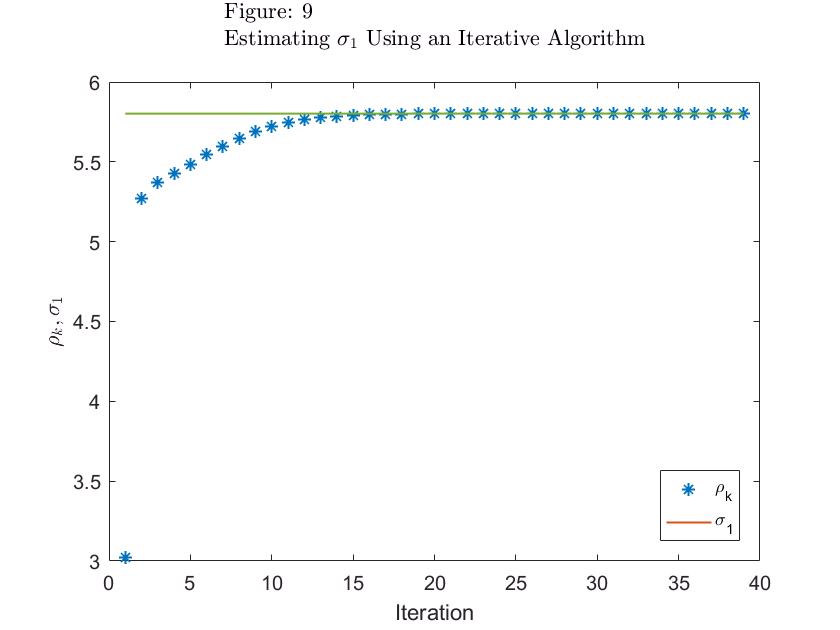

[U,S,V] = svd(G);
singular_values = diag(S); %We want to estimate this value.

tolerance = 10^-6; % The level of tolerance can be adjusted to specify satisfactory 'convergence' of sequenc rho_k
iterations = 0;
error = 1;
X = randn(64,1); %Start with a random vector for the scheme.
errors = error; %We're going to store the error at each iteration

while error > tolerance
    
    iterations = iterations + 1;
    X = G' * G * X / norm(X); %apply the iterative scheme
    rhos(iterations) = sqrt(norm(X));
    %compare rho_k to sigma_1 to test convergence
    error = norm(rhos(iterations) - singular_values(1));
    errors(iterations) = error;
    
end

plot1 = plot(1:length(rhos), rhos,'*', 1:length(rhos),...
    singular_values(1)*(ones(length(rhos))), 'linewidth', 1);
title({['Figure: 9'] ['Estimating $$\sigma_1$$ Using an Iterative Algorithm'] ['']}, 'interpreter', 'latex')
xlabel('Iteration')
ylabel('$$\rho_k, \sigma_1$$', 'interpreter', 'latex')
names = {'\rho_k' , '\sigma_1'};
legend(plot1,names, 'location', 'southeast')


normest_comparison = normest(G) - rhos(end) %Comparing the iterative approximation to the built in 'normest'.

normest_comparison = -1.3239e-06

iterations %We estimated sigma_1 to the level of tolerance after this many iterations

iterations = 39

Based on Figure 9, I had a suspicion about what might occur if we looked at logs of the errors at each step. Plotting the logs of the errors in between the $\rho_k$ sequence and $\sigma_1$, we get something that appears 'almost' linear overall.

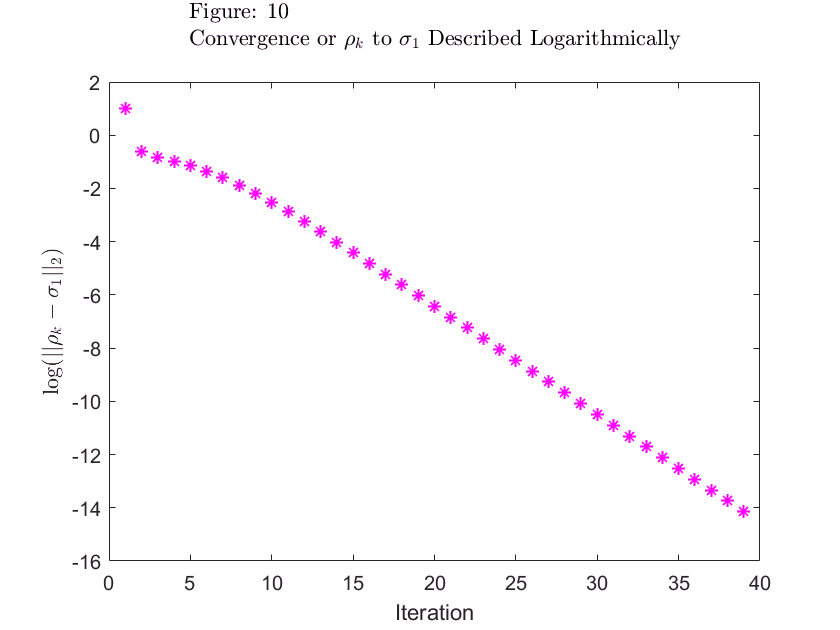

plot1 = plot(1:iterations, log(errors), 'm*', 'linewidth', 1);
title({['Figure: 10'] ['Convergence or $$\rho_k$$ to $$\sigma_1$$ Described Logarithmically'] ['']},...
    'interpreter', 'latex')
xlabel('Iteration')
ylabel('log$$(||\rho_k - \sigma_1||_2)$$', 'interpreter', 'latex')